# **Case C: Macro. AS-AD Curve and Stabilisation Policy**

Consider the **AS-AD model** with *static inflation expectations* (p. 519 in Sørensen and Whitta-Jakobsen):


$$r_{t} =i_{t}-\pi_{t+1}^{e} \\
y_{t} =\overline{y}-\alpha_{2}(r_{t}-\overline{r}^{\ast})+v_{t} \\
i_{t} =\overline{r}^{\ast}+\pi_{t+1}^{e}+h(\pi_{t}-\pi^{\ast})+b(y_{t}-\overline{y}) \\
\pi_{t} = \pi_{t}^{e}+\gamma(y_{t}-\overline{y})+s_{t} \\
\pi_{t}^{e}=\pi_{t-1}
$$


This results in the following **AD-curve**


$$\pi_{t} =\pi^{\star}-\frac{1}{\alpha}(y_{t}-\overline{y}-z_{t})$$


where


$$\alpha = \frac{\alpha_2h}{1+\alpha_2b} \\
z_t = \frac{v_t}{1+\alpha_2b}$$


And the following **SRAS-curve**


$$\pi_{t} =\pi_{t-1}+\gamma(y_{t}-\overline{y})+s_{t}$$


Setting the AD-curve equal to the SRAS-curve the **equilibrium** is


$$y_{t}
=\frac{\pi^{\star}+\frac{1}{\alpha}(\overline{y}+z_{t})-\pi_{t-1}+\gamma\overline{y}-s_{t}}{\frac{1}{\alpha}+\gamma}$$


We can then find $\pi_t$ by either the AD-curve or the SRAS-curve. 

## 1. Setup

First we choose the parameters of the model and save them in the struct `par`.

par = struct();

par.ybar = 0;
par.pi_star = 0;

par.alpha_2 = 5.76;
par.gamma = 0.3;

par.h = 0.5;
par.b = 0.5;

In the bottom of this file, we have three **local functions**:

`AD(y,z,par) `- return $\pi$ values from the AD-curve  

`SRAS(pi_lag,y,par) `- return $\pi$ values from the SRAS-curve

`equilibrium(pi_lag,z,s,par) `- return the equilibrium value of `y`

## 2. Plot the AS-AD curve

Creating a grid for `y`, we can easily plot the AS and AD curves.

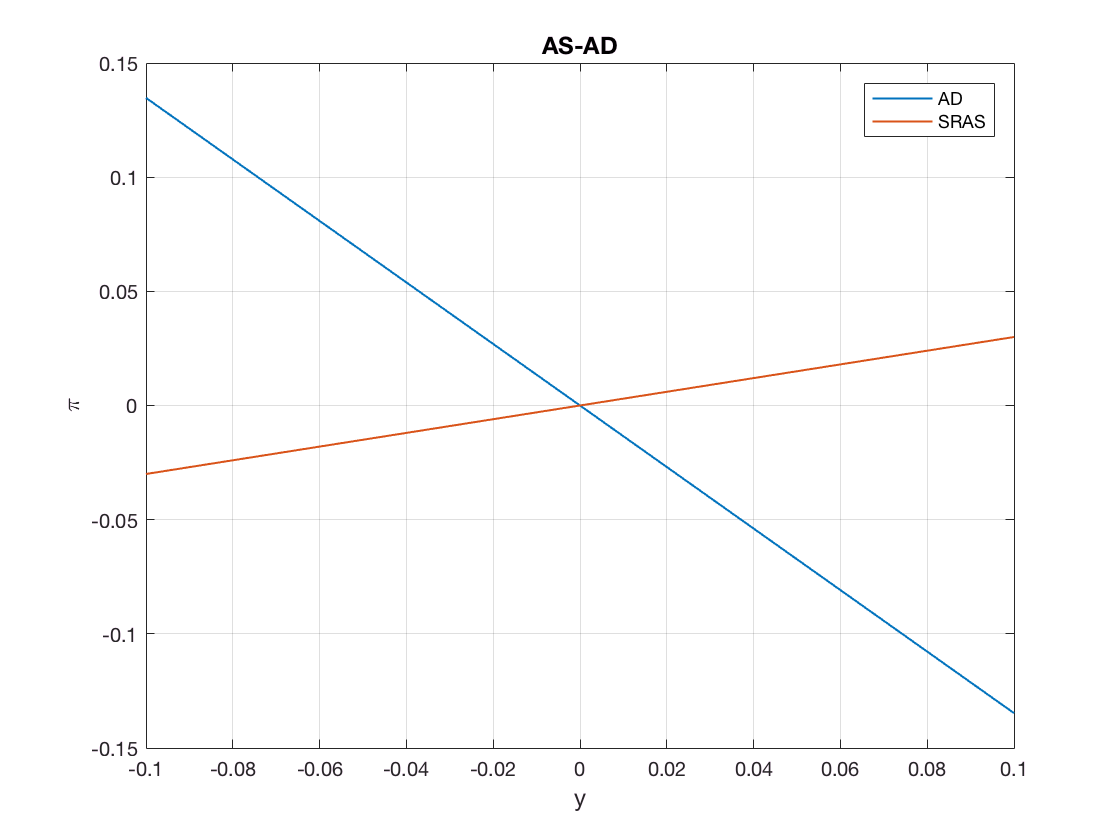

grid_y = linspace(-0.1,0.1,100);
pi_AD = AD(grid_y,0,par);
pi_SRAS = SRAS(par.pi_star,grid_y,0,par);

figure();
hold on;
plot(grid_y,pi_AD,'-','linewidth',1,'DisplayName','AD')
plot(grid_y,pi_SRAS,'-','linewidth',1,'DisplayName','SRAS')
   
title('AS-AD','fontsize',12)
xlabel('y','fontsize',12)
ylabel('\pi','fontsize',12)
legend('Location','northeast')
box('on')
grid on; 
hold off; 

## 3. Plot the convergence after a demand shock (shock to z)

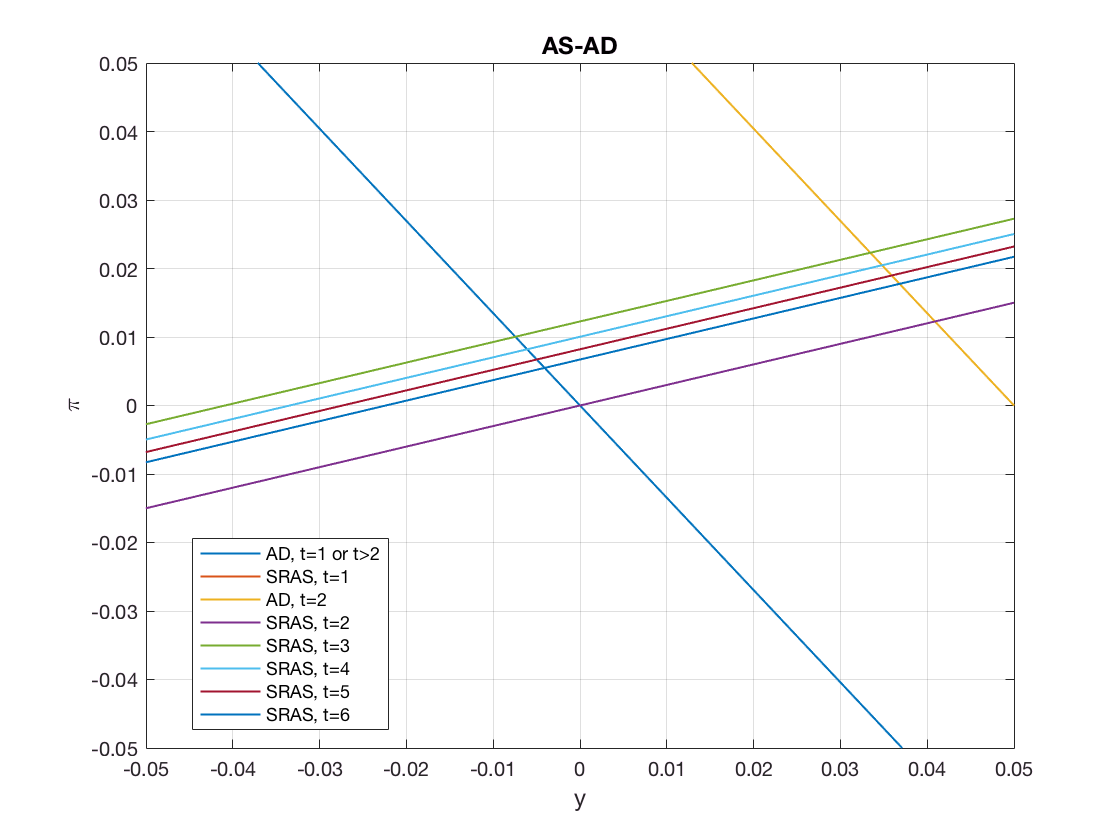

% 1. number of periods
T = 6;

% 2. allocate
y = nan(T,1);
pi = nan(T,1);
z = zeros(T,1);
s = zeros(T,1);

% 3. choose shock
z(2) = 0.05;

% 4. figure
figure();
hold on;

for t = 1:T
    
    % a. lagged inflation
    if t == 1
        pi_lag = par.pi_star;
    else
        pi_lag = pi(t-1);
    end
    
    % b. AD-curve
    pi_AD = AD(grid_y,z(t),par);
    if t == 1
        plot(grid_y,pi_AD,'-','linewidth',1,'DisplayName','AD, t=1 or t>2')    
    elseif t == 2
        plot(grid_y,pi_AD,'-','linewidth',1,'DisplayName','AD, t=2')        
    end 
    
    % c. SRAS-curve
    pi_SRAS = SRAS(pi_lag,grid_y,s(t),par);   
    plot(grid_y,pi_SRAS,'-','linewidth',1,'DisplayName',sprintf('SRAS, t=%d',t))
    
    % d. equilibrium values of GDP and inflation
    y(t) = equilibrium(pi_lag,z(t),s(t),par); 
    pi(t) = AD(y(t),z(t),par);
    
end
   
% layout
xlim([-0.05 0.05])
ylim([-0.05 0.05])
title('AS-AD','fontsize',12)
xlabel('y','fontsize',12)
ylabel('\pi','fontsize',12)
legend('Location','best')
box('on')
grid on; 

## 4. Simulate

If we assume that `v` and `s `are normally distributed and choose

par.T = 500; % number of periods to simulate
par.sigma_v = 0.01; % std. of v shock
par.sigma_s = 0.01; % std. of s shock

then we can simulate the behavior of the model using the local function `simulate(par)`

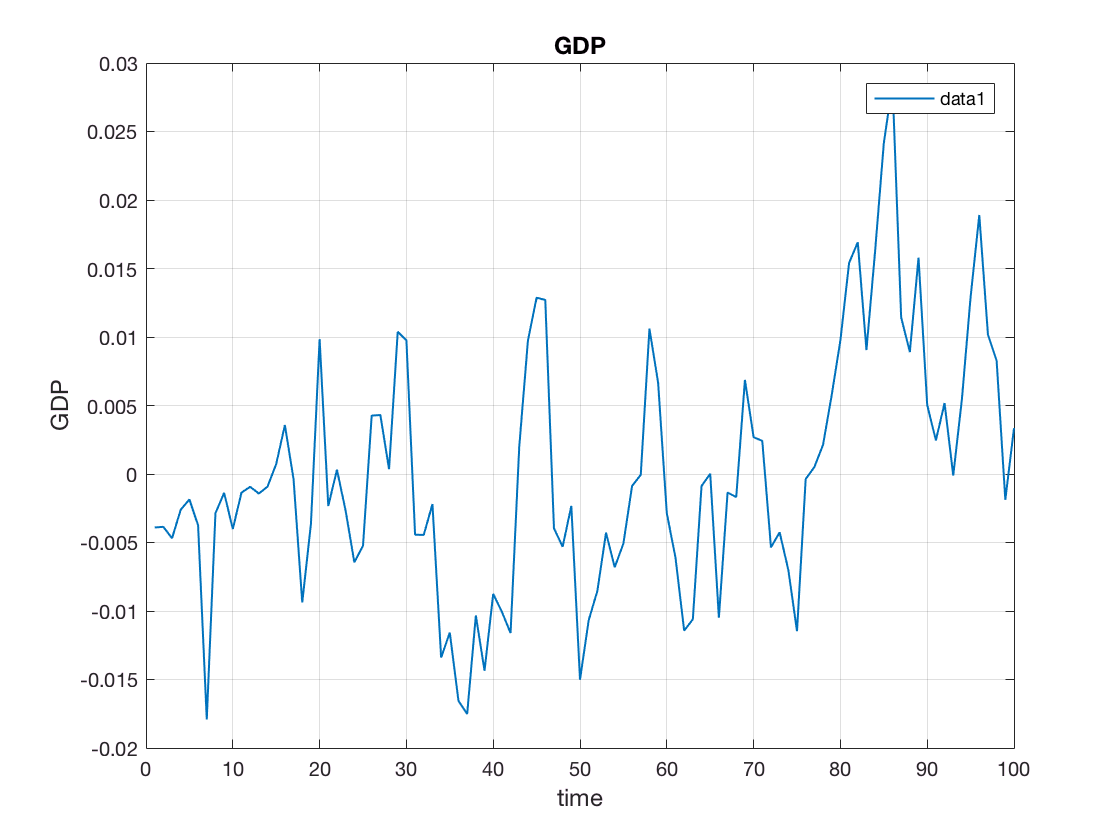

sim = simulate(par);

% plot output
figure();
hold on;
plot(1:100,sim.y(1:100),'-','linewidth',1)
   
title('GDP','fontsize',12)
xlabel('time','fontsize',12)
ylabel('GDP','fontsize',12)
legend('Location','northeast')
box('on')
grid on; 

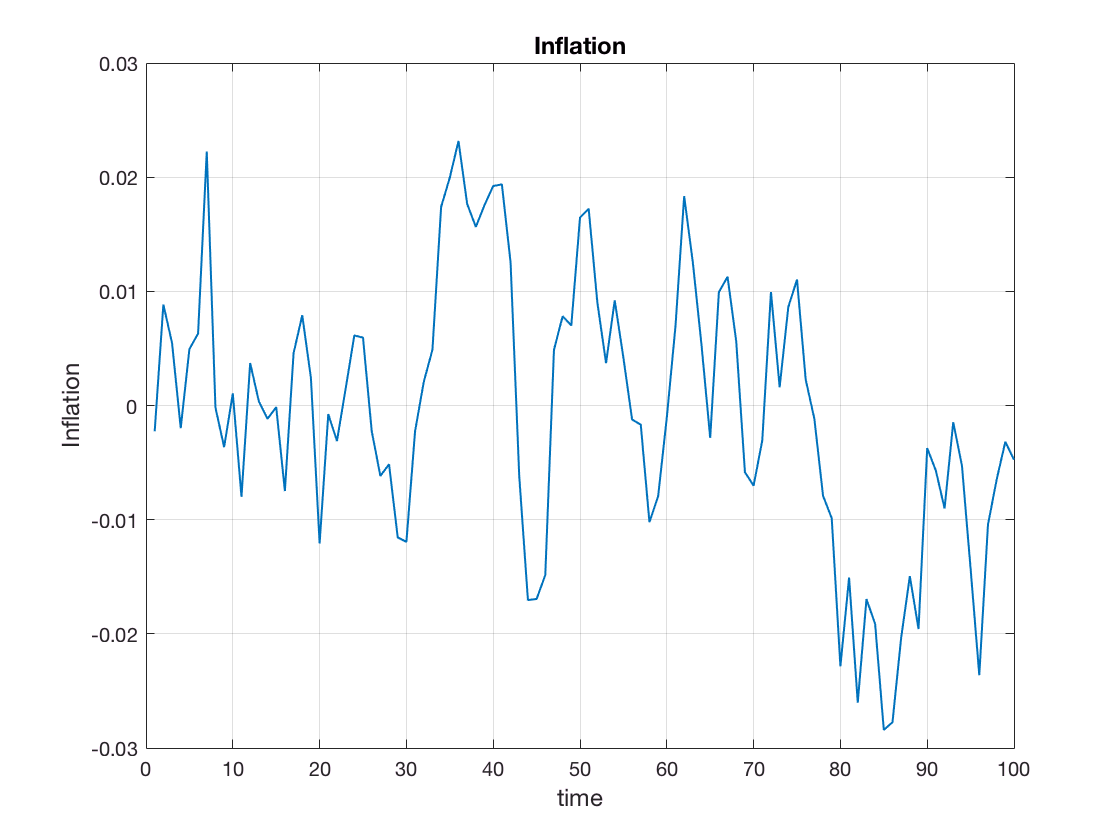


% plot inflation
figure();
hold on;
plot(1:100,sim.pi(1:100),'-','linewidth',1)
   
title('Inflation','fontsize',12)
xlabel('time','fontsize',12)
ylabel('Inflation','fontsize',12)
box('on')
grid on; 

## 5. Stabilization Policy

It is natural to assume that society **dislike fluctuations in GDP and inflation**. Specifically, we assume that the **central bank** seek to choose $b$ and $h$ to minimize the weighted sum of variances of output and inflation. I.e. $b$ and $h$  are chosen by


$$(b^\ast,h^\ast)=\min_{b,h} \omega_y var(y_t) + \omega_\pi var(\pi_t)$$


We choose the following **weighting parameters**

par.omega_y = 1;
par.omega_pi = 1;

We can then make a **3D plot** of the social loss as a function of `b` and `h`.

(This can be rather time consuming)

% a. compute matrix of loss as a function of b and h
Nb = 10;
Nh = 15;
b_vec = linspace(0,1,Nb);
h_vec = linspace(0.3,1,Nh);
loss = nan(Nb,Nh);

wb = waitbar(0,'Evaluating loss function...'); 
for i = 1:Nb
    for j = 1:Nh
        h_ = waitbar((j + (i-1)*Nh)/(Nb*Nh),wb); 
        loss(i,j) = social_loss_bh(b_vec(i),h_vec(j),par);
    end
end
close(wb); 

% b. figure
[b_mat, h_mat] = ndgrid(b_vec,h_vec);

figure()
surf(b_mat,h_mat,loss,'EdgeColor','none')
colorbar;
xlabel('b');
ylabel('h');
zlabel('loss');

We can finally use a constrained optimizer to find the **optimal central bank behavior** in the model.

% a. loss function
f = @(x) social_loss_bh(x(1),x(2),par);

% b. optimizer options
options = optimoptions('fmincon',...
                        'Display','final',...
                        'Algorithm','interior-point',...
                        'StepTolerance',1e-6,...                        
                        'FunctionTolerance',1e-6,...
                        'MaxIterations',500);

% c. bounds
lower_bounds = [0 0];
upper_bounds = [1 1];

% d. initial guess and call optimizer
initial_guess = [0.5 0.5];
[x,fval] = fmincon(f,initial_guess,[],[],[],[],...
                                   lower_bounds,upper_bounds,[],...
                                   options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 

                         
% e. print results                                   
fprintf('optimal b = %5.3f\n',x(1));

optimal b = 0.647


fprintf('optimal h = %5.3f\n',x(2));

optimal h = 0.846


fprintf('minimized loss = %g\n',fval);

minimized loss = 0.000239119


## Further ideas

- Play around with the parameters and see what happens.

- Look at the convergence to a supply shock.

- Introduce *adaptive* rather than *static* expectations.

## LOCAL FUNCTIONS

function pi = AD(y,z,par)
    alpha = par.alpha_2*par.h/(1+par.alpha_2*par.b);
    pi = par.pi_star-1/alpha*(y-par.ybar-z);
end
function pi = SRAS(pi_lag,y,s,par)
    pi = pi_lag+par.gamma*(y-par.ybar)+s;
end
function eq = equilibrium(pi_lag,z,s,par)
    alpha = par.alpha_2*par.h/(1+par.alpha_2*par.b);
    nom = par.pi_star + 1/alpha*(par.ybar+z)-pi_lag+par.gamma*par.ybar-s;
    denom = 1/alpha+par.gamma;        
    eq = nom/denom;        
end
function sim = simulate(par)
        
    rng(2017);
    
    % 1. allocate
    sim = struct();        
    sim.y = nan(par.T,1);
    sim.pi = nan(par.T,1);
    
    % 2. draw random normal shocks
    sim.v = par.sigma_v*randn(par.T,1);
    sim.s = par.sigma_s*randn(par.T,1);
    
    % 3. Calculate z
    sim.z = sim.v/(1+par.alpha_2*par.b);
    
    % 4. Loop over time
    for t = 1:par.T
              
        % a. lagged inflation
        if t == 1
            pi_lag = 0;
        else
            pi_lag = sim.pi(t-1);           
        end
        
        % b. equilibrium
        sim.y(t) = equilibrium(pi_lag,sim.z(t),sim.s(t),par);
        sim.pi(t) = AD(sim.y(t),sim.z(t),par);      
        
        % c. check equilibrium
        pi_alt = SRAS(pi_lag,sim.y(t),sim.s(t),par);        
        assert(abs(sim.pi(t)-pi_alt) < 1e-8);
        
    end
end
function loss = social_loss(par,sim)   
    loss = par.omega_y*var(sim.y) + par.omega_pi*var(sim.pi);
end
function loss = social_loss_bh(b,h,par)   
    par.b = b;
    par.h = h;
    sim = simulate(par);
    loss = social_loss(par,sim);
end